# LABORATORUL 3 STATISTICA 

## ***Problema 1***

**Se lucreaza cu legea normala N(miu, sigma).**

a)distributia statistica(cu frecvente absolute si frecvente relative)

b)histograma frecventelor absolute

c)poligonul frecventelor absolute

d)media aritmetica, geometrica si armonica

e)mediana

f)modul

g)cuartile

h)dispersia si abaterea standard

i)momentele centrate de ordin 1, 2, 3, 4 

mu = 10; 
sigma = 2; 
N = 1000;
X = random('Normal', mu, sigma, 1, N);
X = sort(X,'ascend');
X_min = min(X);
X_max = max(X);
n = fix(1 + 10/3*log10(N));
d = (X_max - X_min)/n;
i = 1:n+1;
c(i) = X_min + (i - 1) .* d;
[f,middle] = hist(X,n);


numar = (1:n)';
clasa = [c(1:n)' c(2:n+1)'];
frecventa_absoluta = f';
mijlocul_clasei = middle';
frecventa_relativa = f'/N;
table(numar,clasa,frecventa_absoluta,mijlocul_clasei,frecventa_relativa)

ans = 11×5 table
    numar         clasa          frecventa_absoluta    mijlocul_clasei    frecventa_relativa
    _____    ________________    __________________    _______________    __________________

      1       3.603    4.8531             4                4.2281               0.004       
      2      4.8531    6.1033            20                5.4782                0.02       
      3      6.1033    7.3534            72                6.7283               0.072       
      4      7.3534    8.6035           136                7.9784               0.136       
      5      8.6035    9.8536           225                9.2286               0.225       
      6      9.8536    11.104           250                10.479                0.25       
      7      11.104    12.354           174                11.729   

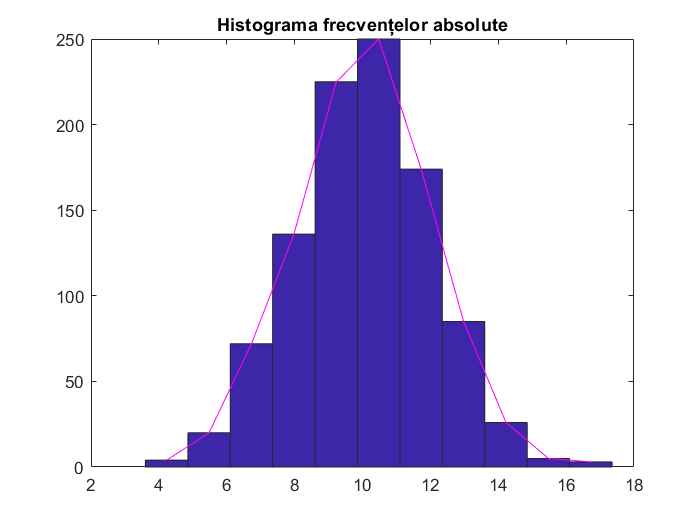


clf
figure(1)
hist(X,n)
title('Histograma frecvențelor absolute')
hold on
plot(middle,f,'magenta')


media_aritmetica=mean(X);
fprintf('Media aritmetica %0f\n', media_aritmetica)

Media aritmetica 10.028946


media_geometrica=geomean(X);
fprintf('Media geometrica %0f\n', media_geometrica)

Media geometrica 9.820399


media_armonica=harmmean(X);
fprintf('Media aritmetica %0f\n', media_armonica)

Media aritmetica 9.596130



mediana = median(X);
fprintf('Medina  %0f\n', mediana)

Medina  10.090320



i = find(f == max(f));
mod = middle(i);
fprintf('Modul  %0f\n', mod)

Modul  10.478666



disp("Cuartilele sunt:")

Cuartilele sunt:


Q_1 = prctile(X,0.25);
Q_2 = prctile(X,0.5);
Q_3 = prctile(X,0.75);

fprintf('Q1 %0f\n', Q_1)

Q1 4.670815


fprintf('Q2 %0f\n', Q_2)

Q2 5.027458


fprintf('Q3 %0f\n', Q_3)

Q3 5.115665



dispersia = var(X);
fprintf('Dispersia %0f\n', dispersia)

Dispersia 3.966597


abaterea_standard=std(X);
fprintf('Abaterea standard %0f\n', abaterea_standard)

Abaterea standard 1.991632




m1 = moment(X,1);
fprintf('Momentul de ordin 1 este %0f\n', m1)

Momentul de ordin 1 este 0.000000


m2 = moment(X,2);
fprintf('Momentul de ordin 2 este %0f\n', m2)

Momentul de ordin 2 este 3.962630


m3 = moment(X,3);
fprintf('Momentul de ordin 3 este %0f\n', m3)

Momentul de ordin 3 este 0.086268


m4 = moment(X,4);
fprintf('Momentul de ordin 4 este %0f\n', m4)

Momentul de ordin 4 este 48.392190


## Problema 2

a = 10; 
b = 20; 
N = 1000;
X = random('Uniform', a, b, 1, N);
X = sort(X,'ascend');
X_min = min(X);
X_max = max(X);
n = fix(1 + 10/3*log10(N));
d = (X_max - X_min)/n;
i = 1:n+1;
c(i) = X_min + (i - 1) .* d;
[f,middle] = hist(X,n);


numar = (1:n)';
clasa = [c(1:n)' c(2:n+1)'];
frecventa_absoluta = f';
mijlocul_clasei = middle';
frecventa_relativa = f'/N;
table(numar,clasa,frecventa_absoluta,mijlocul_clasei,frecventa_relativa)

ans = 11×5 table
    numar         clasa          frecventa_absoluta    mijlocul_clasei    frecventa_relativa
    _____    ________________    __________________    _______________    __________________

      1      10.003     10.91            93                10.456               0.093       
      2       10.91    11.817           101                11.364               0.101       
      3      11.817    12.724            81                12.271               0.081       
      4      12.724    13.632            94                13.178               0.094       
      5      13.632    14.539            98                14.085               0.098       
      6      14.539    15.446           105                14.993               0.105       
      7      15.446    16.353            74                  15.9   

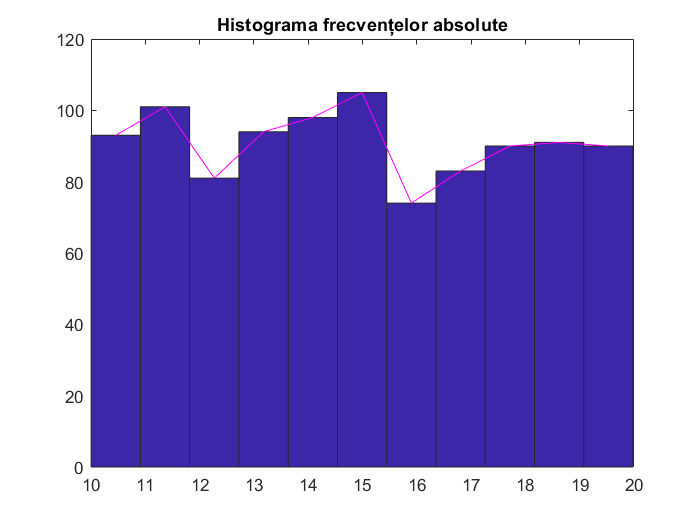


clf
figure(1)
hist(X,n)
title('Histograma frecvențelor absolute')
hold on
plot(middle,f,'magenta')


media_aritmetica=mean(X);
fprintf('Media aritmetica %0f\n', media_aritmetica)

Media aritmetica 14.931041


media_geometrica=geomean(X);
fprintf('Media geometrica %0f\n', media_geometrica)

Media geometrica 14.643881


media_armonica=harmmean(X);
fprintf('Media aritmetica %0f\n', media_armonica)

Media aritmetica 14.355291



mediana = median(X);
fprintf('Medina  %0f\n', mediana)

Medina  14.752530



i = find(f == max(f));
mod = middle(i);
fprintf('Modul  %0f\n', mod)

Modul  14.992536



disp("Cuartilele sunt:")

Cuartilele sunt:


Q_1 = prctile(X,0.25);
Q_2 = prctile(X,0.5);
Q_3 = prctile(X,0.75);

fprintf('Q1 %0f\n', Q_1)

Q1 10.038199


fprintf('Q2 %0f\n', Q_2)

Q2 10.055856


fprintf('Q3 %0f\n', Q_3)

Q3 10.070997



dispersia = var(X);
fprintf('Dispersia %0f\n', dispersia)

Dispersia 8.428334


abaterea_standard=std(X);
fprintf('Abaterea standard %0f\n', abaterea_standard)

Abaterea standard 2.903159




m1 = moment(X,1);
fprintf('Momentul de ordin 1 este %0f\n', m1)

Momentul de ordin 1 este 0.000000


m2 = moment(X,2);
fprintf('Momentul de ordin 2 este %0f\n', m2)

Momentul de ordin 2 este 8.419906


m3 = moment(X,3);
fprintf('Momentul de ordin 3 este %0f\n', m3)

Momentul de ordin 3 este 1.316695


m4 = moment(X,4);
fprintf('Momentul de ordin 4 este %0f\n', m4)

Momentul de ordin 4 este 127.794053


## Problema 3

Aceeasi problema pt legea exponentiala 

mu = 10; 
N = 1000;
X = random('Exponential', mu, 1, N);
X = sort(X,'ascend');
X_min = min(X);
X_max = max(X);
n = fix(1 + 10/3*log10(N));
d = (X_max - X_min)/n;

i = 1:n+1;
c(i) = X_min + (i - 1) .* d;
[f,middle] = hist(X,n);


numar = (1:n)';
clasa = [c(1:n)' c(2:n+1)'];
frecventa_absoluta = f';
mijlocul_clasei = middle';
frecventa_relativa = f'/N;
table(numar,clasa,frecventa_absoluta,mijlocul_clasei,frecventa_relativa)

ans = 11×5 table
    numar             clasa              frecventa_absoluta    mijlocul_clasei    frecventa_relativa
    _____    ________________________    __________________    _______________    __________________

      1      0.00080429        5.6672           421                 2.834               0.421       
      2          5.6672        11.334           242                8.5003               0.242       
      3          11.334            17           140                14.167                0.14       
      4              17        22.666            86                19.833               0.086       
      5          22.666        28.333            51                25.499               0.051       
      6          28.333        33.999            29                31.166               0.029       
    

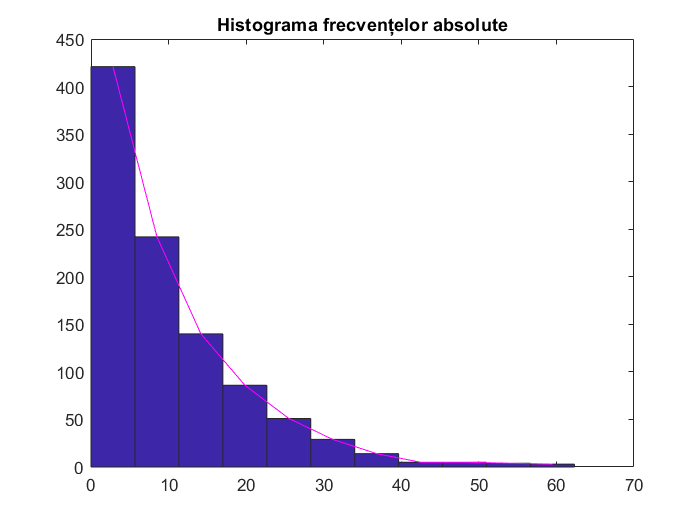


clf
figure(1)
hist(X,n)
title('Histograma frecvențelor absolute')
hold on
plot(middle,f,'magenta')


media_aritmetica=mean(X);
fprintf('Media aritmetica %0f\n', media_aritmetica)

Media aritmetica 10.255695


media_geometrica=geomean(X);
fprintf('Media geometrica %0f\n', media_geometrica)

Media geometrica 5.641743


media_armonica=harmmean(X);
fprintf('Media aritmetica %0f\n', media_armonica)

Media aritmetica 0.456696



mediana = median(X);
fprintf('Medina  %0f\n', mediana)

Medina  7.312547



i = find(f == max(f));
mod = middle(i);
fprintf('Modul  %0f\n', mod)

Modul  2.833982



disp("Cuartilele sunt:")

Cuartilele sunt:


Q_1 = prctile(X,0.25);
Q_2 = prctile(X,0.5);
Q_3 = prctile(X,0.75);

fprintf('Q1 %0f\n', Q_1)

Q1 0.012404


fprintf('Q2 %0f\n', Q_2)

Q2 0.017536


fprintf('Q3 %0f\n', Q_3)

Q3 0.028562



dispersia = var(X);
fprintf('Dispersia %0f\n', dispersia)

Dispersia 99.849503


abaterea_standard=std(X);
fprintf('Abaterea standard %0f\n', abaterea_standard)

Abaterea standard 9.992472




m1 = moment(X,1);
fprintf('Momentul de ordin 1 este %0f\n', m1)

Momentul de ordin 1 este 0.000000


m2 = moment(X,2);
fprintf('Momentul de ordin 2 este %0f\n', m2)

Momentul de ordin 2 este 99.749654


m3 = moment(X,3);
fprintf('Momentul de ordin 3 este %0f\n', m3)

Momentul de ordin 3 este 1735.370908


m4 = moment(X,4);
fprintf('Momentul de ordin 4 este %0f\n', m4)

Momentul de ordin 4 este 68259.096052
